clear all; clc; close all;
global N P measang
% Noise level
noise_level = 0.01;

N = 128;
target = phantom('Modified Shepp-Logan',N);
angle0  = -90;
measang = angle0 + [0:(N-1)]/N*180;
P  = length(radon(target,0));
NP = N*P; % size of y_obs
NN = N^2; % size of x / original image
observation = radon(target,measang);

% Add noise to the data
e = randn(size(observation));
y_obs  = observation + noise_level*max(max(observation))*e;
Data_var = (noise_level)^2; % Covariance matrix for data  \Sigma^{-1} = noise_level

## True solution

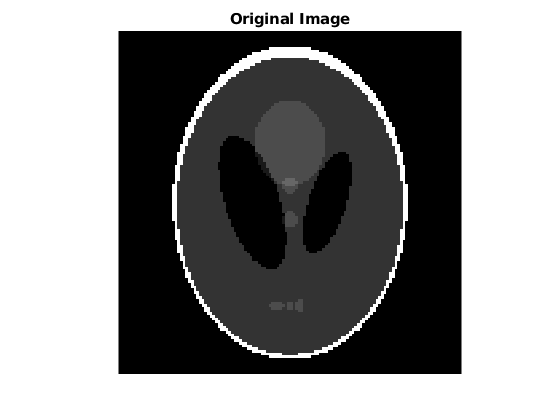

figure
Xtrue = reshape(target,[N,N]);
imagesc(Xtrue)
title('Original Image')
axis square; box off; axis off; colormap gray;
saveas(gcf,['X_ray_True'],'epsc')

max_iters = 700; tol = 1e-7; % For CG coefficients

R = [1 500 2000 5000 10000 12000]

R =            1         500        2000        5000       10000       12000



if isfile('DI_eigenvectors.mat')
    load('DI_eigenvectors.mat')
    load('Eigvec_Active_normal.mat')
else
    [A]=Data(N);
    r = 15000

    % Find matrix C_mean
    C_mean = 1/Data_var^2 * A'*(A*A')*A;
    [VU,S_uc,V] = svd(C_mean);

    S_uc = diag(S_uc); V = V(:,1:r);

    save('DI_eigenvectors','V',"S_uc")

    % Find matrix C
    C = 1/Data_var^2 * A'*(A*A' + y_obs(:)*y_obs(:)')*A;
    [WU,S_cc,W] = svd(C);

    S_cc = diag(S_cc); W = W(:,1:r);

    save('Eigvec_Active_normal','W','S_cc')
end



Save = 1; % Save figure 1 = YES or 0 = NO!

Regularizations = [1e2 1.3e5 1e8];
% Regularizations = [1e2];
for ai = 1:numel(Regularizations)
    ai
    alpha = Regularizations(ai)/1e4;
    Regularization = Regularizations(ai);

## Tikhonov solutions

    % Solve the minimization problem using conjugate gradient method.
    RHS = ATy_x((1/Data_var)*y_obs(:));
    x_0 = zeros(size(RHS));
    matvecc = @(x) ATy_x((1/Data_var)*(Ax_y(x))) + Regularization * x;
    x_CM_Tik = CG(matvecc, RHS, x_0, max_iters, tol, false);

    Error(1,5,ai) = round(norm(x_CM_Tik - target(:),'fro')/norm(target(:),'fro')*100,2);

    X = reshape(x_CM_Tik,[N,N]); imagesc(X);
    axis square; box off; axis off; colormap gray;
    saveas(gcf,['X_ray_Tikhonov_alpha_' num2str(alpha)],'epsc')

## Active Subspace + approximated misfit

    for ri = 1:numel(R)
        r = R(ri);
        W1 = W(:,1:r);

        % Solve the minimization problem using conjugate gradient method.
        RHS = W1*(W1'*(ATy_x((1/Data_var)*y_obs(:))));
        x_0 = zeros(size(RHS));
        matvecc = @(x)  W1*(W1'*(ATy_x((1/Data_var)*Ax_y((W1*(W1'*x)))))) + Regularization * (x - W1 * (W1' * x));
        x_CM_ACT_DI = CG(matvecc, RHS, x_0, max_iters, tol, false);

        Error(ri,1,ai) = round(norm(x_CM_ACT_DI - target(:),'fro')/norm(target(:),'fro')*100,2);

        name = 'ACT';
        Plot_figures(r,alpha,name,x_CM_ACT_DI,N,Save)
    end

## Active Subspace + Approximated misfit + subtracting gradient mean

    for ri = 1:numel(R)
        r = R(ri);
        V1 = V(:,1:r);

        % Solve the minimization problem using conjugate gradient method.
        RHS = V1*(V1'*(ATy_x((1/Data_var)*y_obs(:))));
        x_0 = zeros(size(RHS));
        matvecc = @(x)  V1*(V1'*(ATy_x((1/Data_var)*Ax_y((V1*(V1'*x)))))) + Regularization * (x - V1 * (V1' * x));
        x_CM_ACT_DI = CG(matvecc, RHS, x_0, max_iters, tol, false);

        Error(ri,2,ai) = round(norm(x_CM_ACT_DI - target(:),'fro')/norm(target(:),'fro')*100,2);

        name = 'ACT_M';
        Plot_figures(r,alpha,name,x_CM_ACT_DI,N,Save)
    end

## Active Subspace + Full misfit

    for ri = 1:numel(R)
        r = R(ri);
        W1 = W(:,1:r);

        % Solve the minimization problem using conjugate gradient method.
        RHS = ((ATy_x((1/Data_var)*y_obs(:))));
        x_0 = zeros(size(RHS));
        matvecc = @(x)  ATy_x((1/Data_var)*Ax_y(x)) + Regularization * (x - W1 * (W1' * x));
        x_CM_ACT_DI = CG(matvecc, RHS, x_0, max_iters, tol, false);

        Error(ri,3,ai) = round(norm(x_CM_ACT_DI - target(:),'fro')/norm(target(:),'fro')*100,2);

        name = 'ACT_Full';
        Plot_figures(r,alpha,name,x_CM_ACT_DI,N,Save)
    end



## Active Subspace + Full misfit + subtracting gradient mean

    for ri = 1:numel(R)
        r = R(ri);
        V1 = V(:,1:r);

        % Solve the minimization problem using conjugate gradient method.
        RHS = ATy_x((1/Data_var)*y_obs(:));
        x_0 = zeros(size(RHS));
        matvecc = @(x)  ATy_x((1/Data_var)*Ax_y(x)) + Regularization * (x - V1 * (V1' * x));
        x_CM_ACT_DI = CG(matvecc, RHS, x_0, max_iters, tol, false);

        Error(ri,4,ai) = round(norm(x_CM_ACT_DI - target(:),'fro')/norm(target(:),'fro')*100,2);

        name = 'ACT_M_Full';
        Plot_figures(r,alpha,name,x_CM_ACT_DI,N,Save)

    end
end

save('Result_Err', 'Error');

## EXTRA FUNCTIONS

% Action of matrix A is randon()
% 40.73499999*N/64; Incomprehensible correction factor
% Action of matrix A^{-1} is irandon()*corxn


function [y] = Ax_y(x) % operator A*x
global N measang

y = radon(reshape(x,[N,N]),measang);
y = y(:); % return column size [P*N,1]
end

function x = ATy_x(y)   % operator A'*x
global N P measang

x = 40.73499999*N/64 * iradon(reshape(y,[P,N]), measang, 'none');
x = x(2:end-1, 2:end-1);
x = x(:); % return column size [N*N,1]
end

function y = CG(matvec, RHS, x_0, max_iters, tol, should_print)
y      = x_0;
r      = RHS; % RHS - matvec(0) = RHS since matvec is linear
r_0    = r;
norm_r = norm(r_0,2);
if tol == 0
    tol = min(0.5, norm_r) * norm(r);
else
    tol = tol * norm(r);
end
rho    = r'*r;
i      = 1;
while i <= max_iters && norm(r,2) > tol
    if i==1
        p = r;
    else
        beta  = rho/old_rho;
        old_p = p;
        p     = r + beta*p;
    end
    w          = matvec(p);
    den        = (p'*w);
    a          = rho/den;
    y_old      = y;
    y          = y + a*p;
    r          = r - a*w;
    old_rho    = rho;
    rho        = r'*r;

    %         if should_print && mod(i,5) == 0
    %             fprintf('Iteration %4d of %4d \n',i,max_iters)
    %             fprintf('r norm: %0.4e \n', norm(r,2))
    %         elseif mod(i,100)==0
    %             fprintf('%4d %4d  %0.6e\n',i, max_iters, norm(r,2))
    %         end
    i = i+1;
end
end



function [A]=Data(N)

target = phantom('Modified Shepp-Logan',N);

% Choose measurement angles (given in degrees, not radians).

Nang    = N;
angle0  = -90;
measang = angle0 + [0:(Nang-1)]/Nang*180;

% Initialize measurement matrix of size (M*P) x N^2, where M is the number of
% X-ray directions and P is the number of pixels that Matlab's Radon
% function gives.
P  = length(radon(target,0));
M  = length(measang);
A = zeros(M*P,N^2);

% Construct measurement matrix column by column. The trick is to construct
% targets with elements all 0 except for one element that equals 1.
for mmm = 1:M
    for iii = 1:N^2
        tmpvec                  = zeros(N^2,1);
        tmpvec(iii)             = 1;
        A((mmm-1)*P+(1:P),iii) = radon(reshape(tmpvec,N,N),measang(mmm));
    end
end
end



function []=Plot_figures(r,alpha,name,x_CM_ACT_DI,N,Save)
if Save == 1
    figure
    if alpha == 0.01
        X = reshape(x_CM_ACT_DI,[N,N]);
        imagesc(X); axis square; box off; axis off; colormap gray;
        saveas(gcf,['X_ray_' name '_r_' num2str(r) '_alpha_001'],'epsc')
    else
        X = reshape(x_CM_ACT_DI,[N,N]);
        imagesc(X); axis square; box off; axis off; colormap gray;
        saveas(gcf,['X_ray_' name '_r_' num2str(r) '_alpha_' num2str(alpha)],'epsc')
    end

end
end